# Interpolate flying height ratio

In this script, we quantify the ratio of bird flying at windturbine height and compute a ratio of the bird density flying at this altititude bin. 

## Load data

load('../2018/data/dc_corr')
load('../2018/data/BelowRadarMPS.mat');
load('../2018/data/Density_estimationMap','g');

Define standard windturbine height

windturbine_minheight = 60;
windturbine_maxheight = 150;

## Compute ratio at weather radar location

Get bird density integrated over entire height and windturbine height with and without the interpolation

denss_wt = nan(numel(dc(1).time),numel(dc),30); 
denss_tt = nan(numel(dc(1).time),numel(dc),30);
denss_wt_s = nan(numel(dc(1).time),numel(dc),1); 
denss_tt_s = nan(numel(dc(1).time),numel(dc),1);
for i_d=1:numel(dc)
    
    % bin height to integrate the full profile (0-200)
    tmp_tt = min(max(dc(1).alt+100-dc(i_d).heightDEM,0),200);

    % bin height to integrate the over windturbine height
    tmp1 = min(max((dc(i_d).heightDEM+windturbine_maxheight) - (dc(1).alt-100),0),200);
    tmp2 = min(max((dc(i_d).heightDEM+windturbine_minheight) - (dc(1).alt-100),0),200);
    tmp_wt = tmp1 - tmp2;
    
    % without simulation (no data => 0)
    tmp4 = dc(i_d).dens4;
    tmp4(:,1:dc(i_d).scatter_lim-1) = nan;
    
    denss_tt_s(:,i_d,1) = sum(tmp4 .* tmp_tt,2,'omitnan'); % bird/km^3 * m
    denss_wt_s(:,i_d,1) = sum(tmp4 .* tmp_wt,2,'omitnan'); % bird/km^3 * m

    %  with MPS simulation
    for i_s = 1:30
        tmp4(:,1:dc(i_d).scatter_lim-1) = MPS{i_d}(:,1:dc(i_d).scatter_lim-1,i_s);
        denss_tt(:,i_d,i_s) = sum(tmp4 .* tmp_tt,2,'omitnan');
        denss_wt(:,i_d,i_s) = sum(tmp4 .* tmp_wt,2,'omitnan');
    end
end

Compute ratio

ratio = denss_wt./denss_tt / (windturbine_maxheight-windturbine_minheight); % 1 / m 
ratio_m = mean(ratio,3,'omitnan');
ratio_s = denss_wt_s./denss_tt_s / (windturbine_maxheight-windturbine_minheight);

clear unused variable

clear MPS tmp*

Compute NNT

NNT = datenum(repmat(dc(1).time',1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

## Exploratory spatio-temporal variation of the ratio

### How many radar are covering windturbine height?

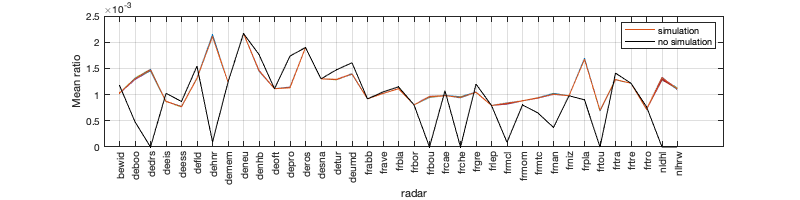

figure('position',[0 0 800 200]); hold on;
f=plot(permute(nanmean(ratio,1),[2 3 1]));
f(1)=plot(nanmean(ratio_s,1),'k');
xticks(1:numel(dc)); xticklabels({dc.name}); xtickangle(90)
xlabel('radar'); ylabel('Mean ratio'); box on; grid on; legend(f([end 1]),'simulation','no simulation')

### **How much bird are flying over wind-turbine height?**

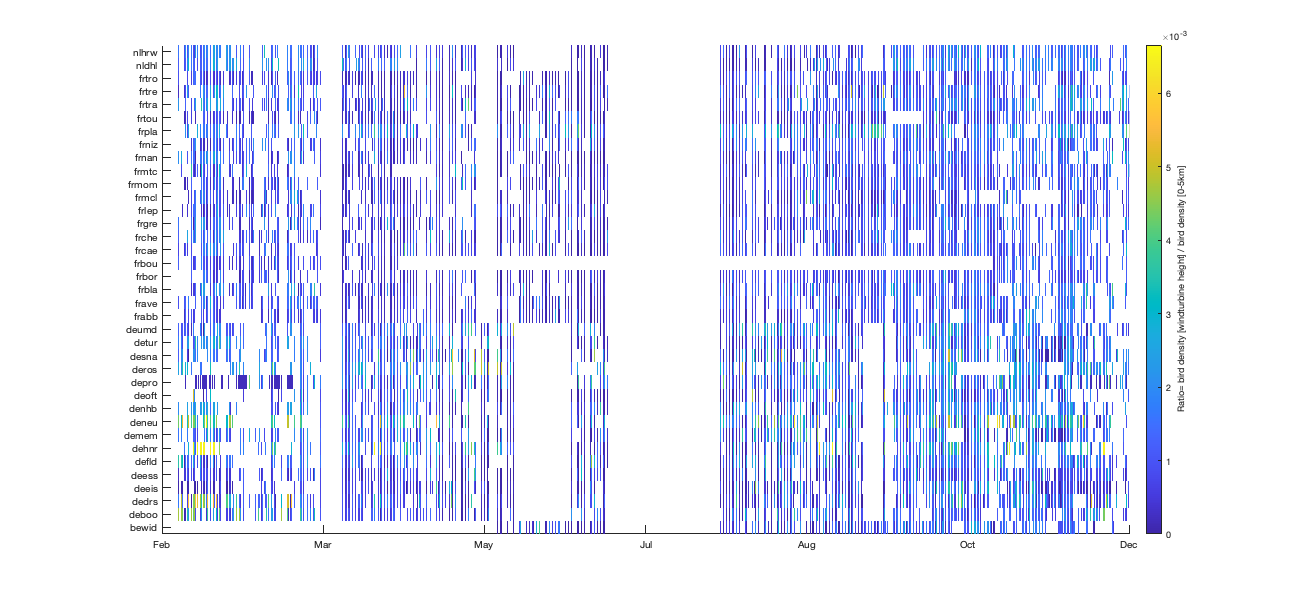

figure('position',[0 0 1300 600]); hold on;
imagesc(datenum(dc(1).time),1:numel(dc),ratio_m', 'AlphaData',double(0~=denss_tt(:,:,1)'));
axis tight; view(2); yticks(1:numel(dc)); yticklabels({dc.name}); %xtickangle(90)
datetick('x','keepticks'); c=colorbar; c.Label.String='Ratio= bird density [windturbine height] / bird density [0-5km]';

### Temporal and radar variation of the ratio per day

Group per day to see more easily

tmp=dateshift(dc(1).time,'start','day','nearest');
[day_id,day]=findgroups(datenum(tmp));
G = findgroups(day_id);
denss_wt_d = splitapply(@nanmean,nanmean(denss_wt,3),G');
denss_tt_d = splitapply(@nanmean,nanmean(denss_tt,3),G');

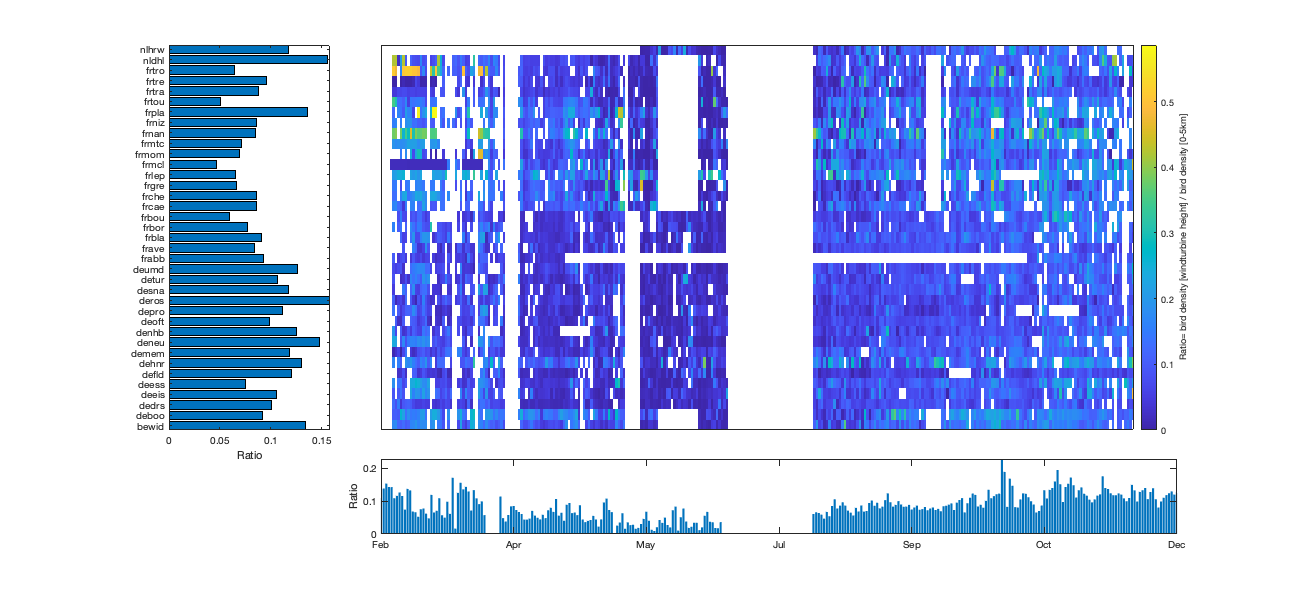

figure('position',[0 0 1300 600]); hold on;
subplot(5,5,[2 20])
imagesc(datenum(dc(1).time),1:numel(dc),(denss_wt_d./denss_tt_d)', 'AlphaData',double(0~=denss_tt_d'));
c=colorbar; c.Label.String='Ratio= bird density [windturbine height] / bird density [0-5km]';
view(2); datetick('x','keepticks'); %xtickangle(90) colorbar; 
xticks([]); yticks([]);
subplot(5,5,[1 16]);
barh(nansum(denss_wt(:,:,2))./nansum(denss_tt(:,:,2)))
yticks(1:numel(dc)); yticklabels({dc.name}); axis tight;xlabel('Ratio')
subplot(5,5,[22 25]);
bar(nansum(denss_wt_d,2)./nansum(denss_tt_d,2)); axis tight; ylabel('Ratio')
datetick('x','keepticks');

### Spatial variation of the ratio

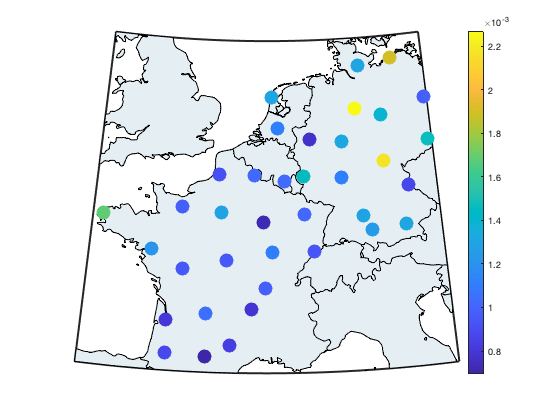

figure;
h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','facecolor',[228 238 243]./255); %geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc.lat],[dc.lon],200,nanmean(ratio_m),'filled'); colorbar;

### Intra-night variation

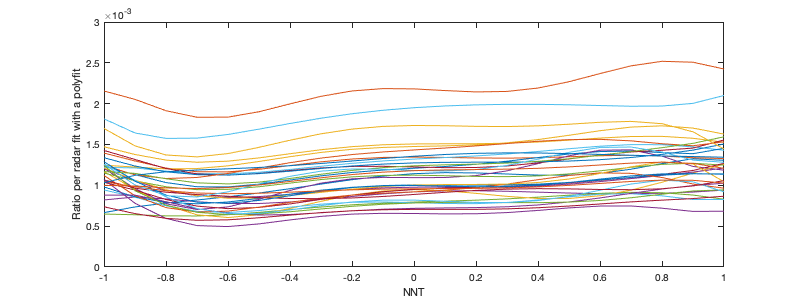

figure('position',[0 0 800 300]); hold on;
p_=8; p=nan(p_,numel(dc));
for i_d=1:numel(dc)
    p(:,i_d)=polyfit(NNT(~isnan(ratio_m(:,i_d)),i_d),ratio(~isnan(ratio_m(:,i_d)),i_d),p_-1);
    plot(-1:.1:1,polyval(p(:,i_d),-1:.1:1))
end
xlabel('NNT'); ylabel('Ratio per radar fit with a polyfit'); box on;

### Variation of ratio as a function of density

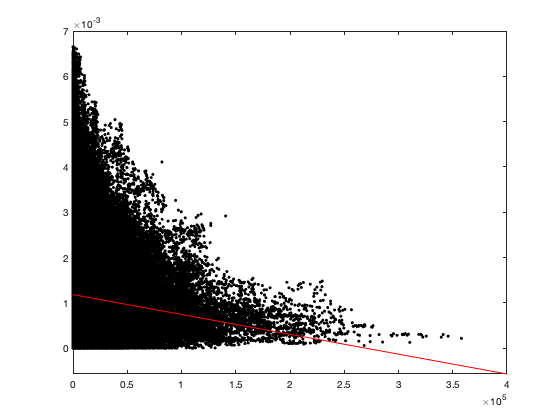

figure;
plot(reshape(denss_tt(:,:,2),1,[]),ratio_m(:),'.k');a=lsline; a.Color='r';

## Interpolation with Generalized linear model (GLM)

After exploring the spatio-temporal variation,we need to come up with a method to interpolate the ratio on the same grid than the energy data (0.25° -1hr)

### Prepare and format data for glm

Construct the table for fitting

Tfit = table(ratio_m(:), ...
    repelem([dc.lat]',numel(dc(1).time),1), ...
    repelem([dc.lon]',numel(dc(1).time),1), ...
    NNT(:), ...
    repmat(datenum(dc(1).time-dc(1).time(1))',numel(dc),1),...
    reshape(denss_tt(:,:,1),[],1),...
    reshape(repmat(1:37,size(ratio_m,1),1),[],1),...
    'VariableNames',{'ratio','lat','lon','NNT', 'time','dens_tt', 'radar'});

remove nan for the fitting

Tfit(isnan(Tfit.ratio),:)=[];
Tfit(Tfit.NNT>1|Tfit.NNT<-1,:)=[];

Remove value with little/no impact (i.e. no bird)

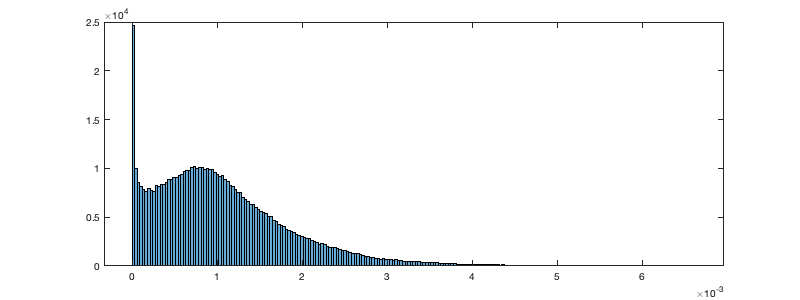

%[f,x] = ecdf(Tfit.dens_tt); max(x(f<0.1))
Tfit(Tfit.dens_tt<1000,:)=[];
figure('position',[0 0 800 300]); histogram(Tfit.ratio)

### Choose model specification with a stepwise glm

Construct the model specification for each variable at the time (lat-lon, time and NNT)

mdllatlon = stepwiseglm(Tfit,'constant', 'ResponseVar', 'ratio',  'PredictorVars', {'lat','lon'},'Weights',Tfit.dens_tt, 'Verbose',0,'Upper','poly44') % same as ,'Criterion','bic'

mdllatlon = Generalized linear regression model:
    ratio ~ 1 + lat*lon + lat^2 + lon^2 + (lat^2):lon + lat:(lon^2) + lat^3 + lon^3 + (lat^2):(lon^2) + lat:(lon^3) + lon^4
    Distribution = Normal

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)       -0.20762      0.011193    -18.549    8.7724e-77
    lat                 0.0137    0.00072614     18.867    2.2482e-79
    lon              -0.010988    0.00057043    -19.262    1.1834e-82
    lat:lon         0.00046623    2.4859e-05     18.755    1.8544e-78
    lat^2          -0.00030118      1.57e-05    -19.183    5.3898e-82
    lon^2           0.00038224    2.7125e-05   

mdltime = stepwiseglm(Tfit,'constant', 'ResponseVar', 'ratio',  'PredictorVars', 'time','Weights',Tfit.dens_tt, 'Verbose',0,'Upper','poly9') % same with ,'Criterion','bic'

mdltime = Generalized linear regression model:
    ratio ~ 1 + time + time^2 + time^3
    Distribution = Normal

Estimated Coefficients:
                    Estimate          SE         tStat     pValue
                   ___________    __________    _______    ______

    (Intercept)      0.0019087    1.4167e-05     134.73      0   
    time           -2.2642e-05    2.6792e-07    -84.511      0   
    time^2          1.1324e-07     1.436e-09     78.861      0   
    time^3         -1.4857e-10      2.37e-12    -62.691      0   


586135 observations, 586131 error degrees of freedom
Estimated Dispersion: 0.0057
F-statistic vs. constant model: 2.73e+04, p-value = 0

mdlNNT = stepwiseglm(Tfit,'constant', 'ResponseVar', 'ratio',  'PredictorVars', 'NNT','Weights',Tfit.dens_tt, 'Verbose',0,'Upper','poly9') % goes up to ^9 with ,'Criterion','bic'

mdlNNT = Generalized linear regression model:
    ratio ~ 1 + NNT + NNT^2 + NNT^3 + NNT^4 + NNT^5 + NNT^6 + NNT^7
    Distribution = Normal

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)      0.0010171    1.8974e-06     536.05              0
    NNT             0.00039666    1.0237e-05     38.747              0
    NNT^2           -5.894e-05     2.489e-05     -2.368       0.017884
    NNT^3           -0.0016965    7.8567e-05    -21.593    2.2723e-103
    NNT^4          -0.00038228    7.2533e-05    -5.2703     1.3622e-07
    NNT^5            0.0047662    0.00017212     27.691    1.1429e-168
    NNT^6      

The stepwiseglm with all variable at the same time takes too much time to run

% modelspec = 'ratio ~ lat*lon + lat^2 + lon^2 + (lat^2):lon + lat:(lon^2) + lat^3 + lon^3 + (lat^2):(lon^2) + lat:(lon^3) + lon^4 + time + time^2 + time^3 + NNT + NNT^2 + NNT^3 + NNT^4 + NNT^5 + NNT^6 + NNT^7';
% mdl = stepwiseglm(Tfit,modelspec, 'ResponseVar', 'ratio',  'PredictorVars', {'lat','lon','NNT','time'},'Weights',Tfit.dens_tt, 'Verbose',2,'Upper','poly7777')  

### Build GLM model

From the stepwise glm, we build the combined model:

modelspec = 'ratio ~ lat*lon + lat^2 + lon^2 + (lat^2):lon + lat:(lon^2) + lat^3 + lon^3 + (lat^2):(lon^2) + lat:(lon^3) + lon^4 + time + time^2 + time^3 + NNT + NNT^2 + NNT^3 + NNT^4 + NNT^5 + NNT^6 + NNT^7';
mdl = fitglm(Tfit, modelspec,'Weights',Tfit.dens_tt)

mdl = Generalized linear regression model:
    ratio ~ 1 + NNT + time + lat*lon + lat^2 + lon^2 + NNT^2 + time^2 + (lat^2):lon + lat:(lon^2) + lat^3 + lon^3 + NNT^3 + time^3 + (lat^2):(lon^2) + lat:(lon^3) + lon^4 + NNT^4 + NNT^5 + NNT^6 + NNT^7
    Distribution = Normal

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)              0             0        NaN            NaN
    lat             -8.838e-05    1.2964e-05    -6.8171     9.2969e-12
    lon                      0             0        NaN            NaN
    NNT             0.00040718    8.9518e-06     45.486              0
    time            -2.546e-05    2.4618e-07    -103.42

### Other model tested

Other distribution of error: Removing the 0, we could fit a gamma:

% Tfit0=Tfit; Tfit0.ratio(Tfit.ratio==0)=0.001;
% mdl0 = fitglm(Tfit0, 'ratio ~ lat + lon + NNT + NNT^2 + NNT^3 + NNT^4 + NNT^5 + time + time^2 + time^3','distribution','gamma','Weights',Tfit0.dens_tt)

GLME (using radar as random variable)

% mdlglme = fitglme(Tfit, 'ratio ~ lat + lon + NNT + NNT^2 + NNT^3 + NNT^4 + NNT^5 + time + time^2 + time^3 + (1|radar)')

GAM

% mdlgam = fitrgam(Tfit,'ratio ~ lat + lon + NNT + time') 
% yFit = resubPredict(Mdl)

Scatter interpolation (not used)

% ratio_coord_time = 13;
% 
% time_data_day=datenum(dateshift(dc(1).time,'start','day','nearest'));
% [day_id,day]=findgroups(time_data_day);
% 
% time_grid_day=datenum(dateshift(g.time,'start','day','nearest'));
% ratio_imterp = nan(g.nlat,g.nlon,g.nt);
% for i=1:numel(day)
%     datetime(day(i),'ConvertFrom','datenum');
%     id = day_id==i;
%     v=denss_wt(id,:,2)./denss_tt(id,:,2);
%     lat = repmat([dc.lat],sum(id),1);
%     lon = repmat([dc.lon],sum(id),1);
%     t = repmat(datenum(dc(1).time(id))',1,numel(dc));
%     Fnn = scatteredInterpolant(lat(~isnan(v)),lon(~isnan(v)),t(~isnan(v)).*ratio_coord_time,v(~isnan(v)),'natural','nearest');
%     ratio_imterp(:,:,time_grid_day == day(i)) = Fnn({g.lat,g.lon,datenum(g.time(time_grid_day == day(i)))});
% end

### Modeling all 30 simulations directly

% Tfit30 = table(ratio(:), ...
%     repmat(repelem([dc.lat]',numel(dc(1).time),1),30,1), ...
%     repmat(repelem([dc.lon]',numel(dc(1).time),1),30,1), ...
%     repmat(NNT(:),30,1) , ...
%     repmat(repmat(datenum(dc(1).time-dc(1).time(1))',numel(dc),1),30,1),...
%     denss_tt(:),...
%     'VariableNames',{'ratio','lat','lon','NNT', 'time','dens_tt'});

Using the 30 simulation, there are multiple duplicate value which fitglm does not like. We can account for those duplicate by removing them from the table and inscreasing their weight in the glm

% [Tfit2,~,ic]=unique(Tfit30,'rows');
% occ=histcounts(ic,0.5:1:height(Tfit2)+.5)';
% w=Tfit2.dens_tt.*occ;
% [f,x] = ecdf(w); id = Tfit2.dens_tt<max(x(f<0.01));
% Tfit2(id,:)=[];

% mdl2 = fitglm(Tfit2, modelspec,'Weights',w)

Or we can test with sub-sampling the table

% mdl3 = fitglm(Tfit(randsample(height(Tfit),1000),:), 'ratio ~ time + time^2 + time^3')

## Analysing the uncertainty

### Inspect GLM residual

Fit a normal distribution on the residuals

resdist = fitdist(mdl.Residuals.Raw,'Normal')

resdist =   NormalDistribution

  Normal distribution
       mu =  2.1996e-05   [2.01541e-05, 2.3838e-05]
    sigma = 0.000719512   [0.000718212, 0.000720816]


Illustration

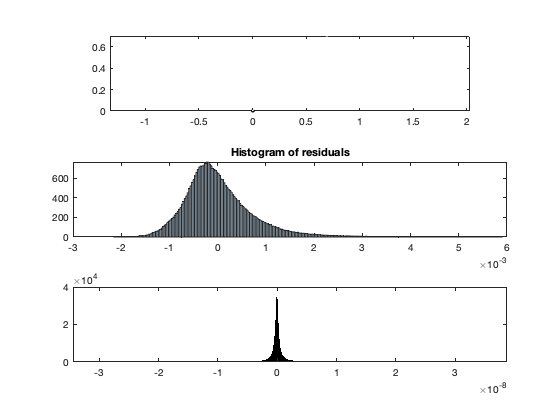

figure; 
subplot(3,1,1); hold on; box on;
plot(Tfit.ratio, mdl.Fitted.Response,'.k'); a=lsline; a.Color='r'; plot([0 .7],[0 .7],'w'); axis equal
subplot(3,1,2); hold on; box on;
plotResiduals(mdl)
x_lim=xlim;
plot(x_lim(1):.01:x_lim(end), resdist.pdf(x_lim(1):.01:x_lim(end)),'r','linewidth',2)
subplot(3,1,3);
histogram(mdl.Residuals.Raw.*Tfit.dens_tt./sum(Tfit.dens_tt))

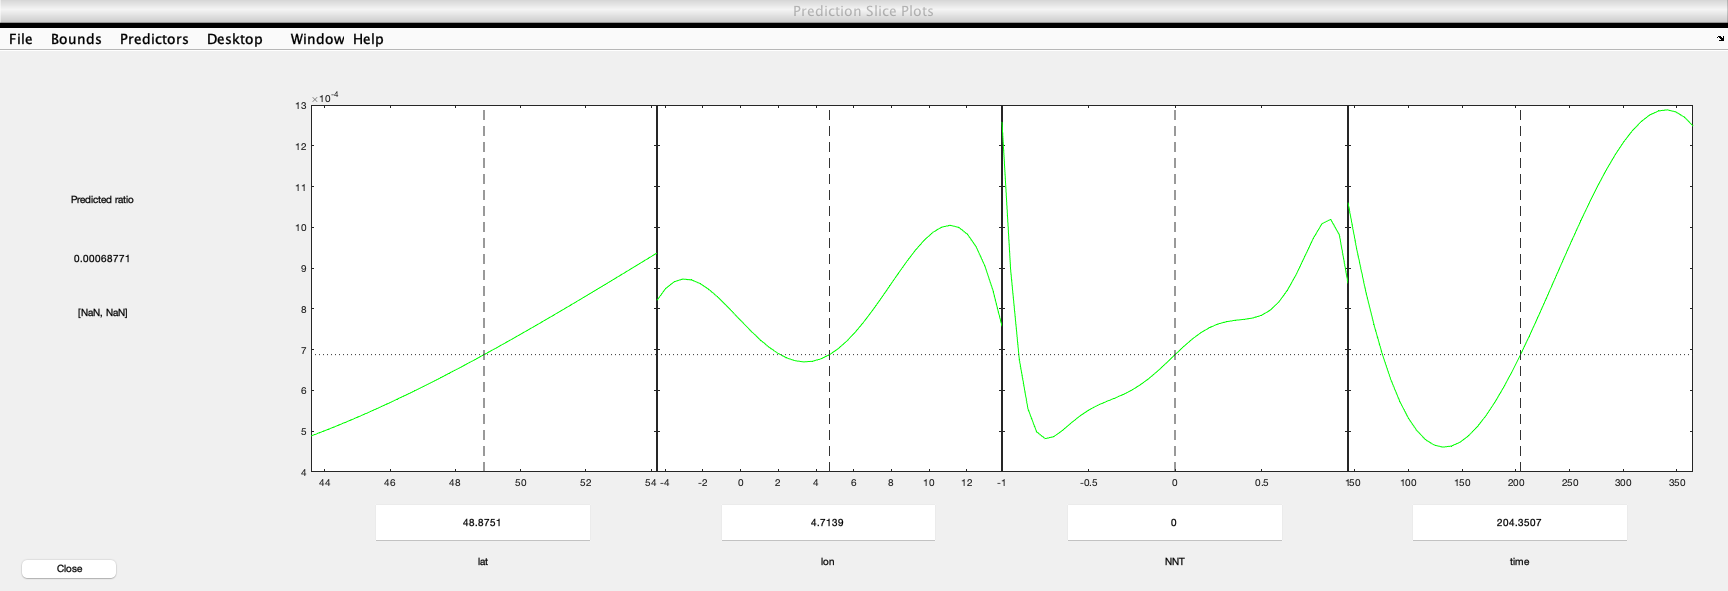

%plotDiagnostics(mdl)
% plotResiduals(mdl)
plotSlice(mdl)

%plotPartialDependence(mdl,'NNT')

### Fit vs empirical value 

RatioPred = reshape(predict(mdl,[g.lat2D(:) g.lon2D(:) zeros(numel(g.lat2D),1) 182.*ones(numel(g.lat2D),3)]),size(g.lat2D));

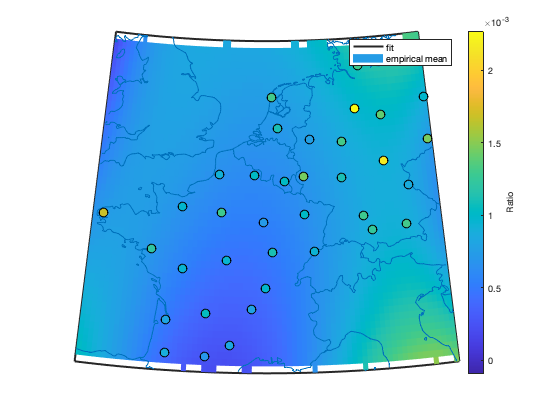

figure;
hold on; h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
surfm(g.lat2D, g.lon2D, RatioPred) 
bordersm('countries')
scatterm([dc.lat], [dc.lon], 80, nanmean(ratio_m),'filled','MarkerEdgeColor','k'); 
c=colorbar;c.Label.String='Ratio'; legend('fit','empirical mean')

[G,G_NNT]=findgroups(round(Tfit.NNT,2));
[G_ratio] = splitapply(@nanmean,Tfit.ratio,G);
[RatioPred2,RatioPredIC2] = predict(mdl,[[mean(Tfit.lat) mean(Tfit.lon)].*ones(numel(G_NNT),2) G_NNT mean(Tfit.time).*ones(numel(G_NNT),3)]);

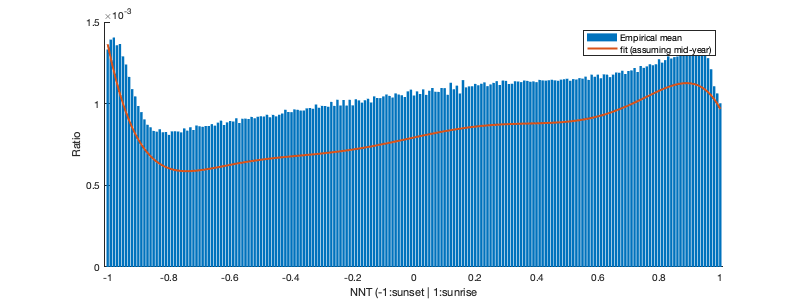

figure('position',[0 0 800 300]); hold on;
bar(G_NNT,G_ratio,'DisplayName','Empirical mean')
plot(G_NNT,RatioPred2,'linewidth',2,'DisplayName','fit (assuming mid-year)'); 
% plot(G_NNT,RatioPredIC2,'--k','linewidth',2); 
% plot(G_NNT,random(mdl,[[49 6].*ones(numel(G_NNT),2) G_NNT mean(Tfit.time).*ones(numel(G_NNT),2)]),'.'); 
xlabel('NNT (-1:sunset | 1:sunrise');ylabel('Ratio');legend()

[G,G_time]=findgroups(round(Tfit.time,0));
[G_ratio] = splitapply(@nanmean,Tfit.ratio,G);
[RatioPred3,RatioPredIC3] = predict(mdl,[[49 6 0].*ones(numel(G_time),3) G_time ones(numel(G_time),2)]);

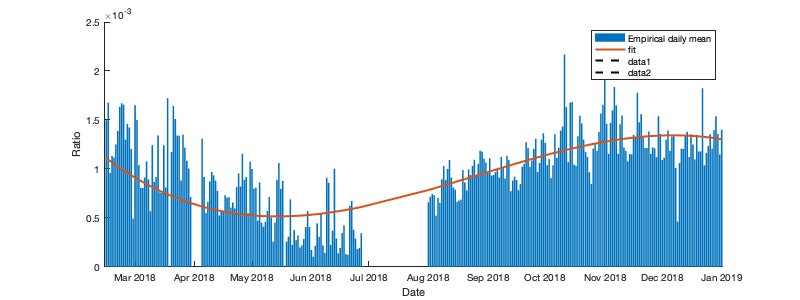

G_timedate= datetime(datenum(dc(1).time(1))+G_time,'ConvertFrom','datenum');
figure('position',[0 0 800 300]); hold on;
bar(G_timedate,G_ratio,'DisplayName','Empirical daily mean')
plot(G_timedate,RatioPred3,'linewidth',2,'DisplayName','fit')
plot(G_timedate,RatioPredIC3,'--k','linewidth',2); 
xlabel('Date'); ylabel('Ratio'); legend()

### Check Residuals with simulation from MPS

Tfit30 = table(ratio(:), ...
    repmat(repelem([dc.lat]',numel(dc(1).time),1),30,1), ...
    repmat(repelem([dc.lon]',numel(dc(1).time),1),30,1), ...
    repmat(NNT(:),30,1) , ...
    repmat(repmat(datenum(dc(1).time-dc(1).time(1))',numel(dc),1),30,1),...
    denss_tt(:),... 
    repmat(reshape(repmat(1:37,size(ratio_m,1),1),[],1),30,1),...
    'VariableNames',{'ratio','lat','lon','NNT', 'time','dens_tt','radar'});


tmp  = predict(mdl, [repelem([dc.lat]',numel(dc(1).time),1) repelem([dc.lon]',numel(dc(1).time),1) NNT(:) repmat(datenum(dc(1).time-dc(1).time(1))',numel(dc),1) reshape(denss_tt(:,:,1),[],1) reshape(repmat(1:37,size(ratio_m,1),1),[],1)]);
tmp(tmp<0)=0;
tmp(tmp>1)=1;
Tfit30.error = reshape(ratio-reshape(tmp,size(NNT)),[],1);

Limit size a bit

Tfit30(isnan(Tfit30.ratio),:)=[];
Tfit30(Tfit30.NNT>1|Tfit30.NNT<-1,:)=[];
Tfit30(Tfit30.dens_tt<1000,:)=[];

Fit distribution

resdist = fitdist(Tfit30.error(:),'Normal')

resdist =   NormalDistribution

  Normal distribution
       mu = 2.85153e-05   [2.81617e-05, 2.88689e-05]
    sigma = 0.000756504   [0.000756254, 0.000756754]


Illustration

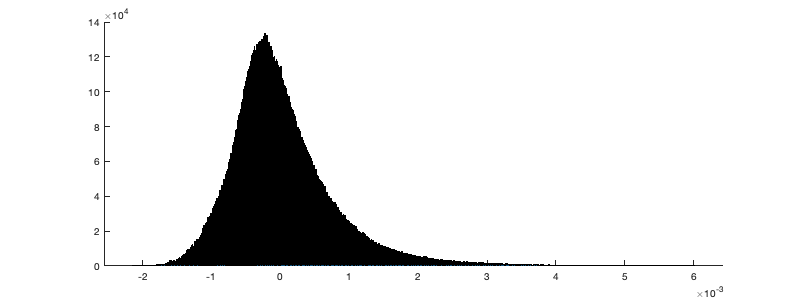

figure('position',[0 0 800 300]); hold on;
histogram(Tfit30.error);

% plot(-1:0.01:1,resdist.pdf(-1:0.01:1)*10^5/4,'r','linewidth',2)

### Resdiual by radar

Illustration

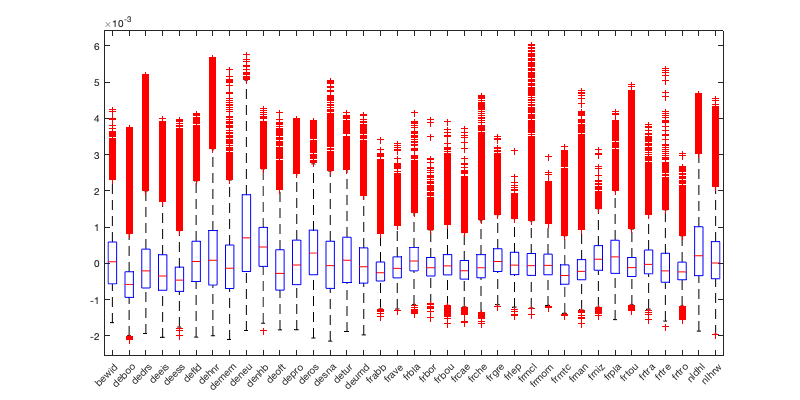

figure('position',[0 0 800 400]); boxplot(Tfit30.error, Tfit30.radar); xticklabels({dc.name});

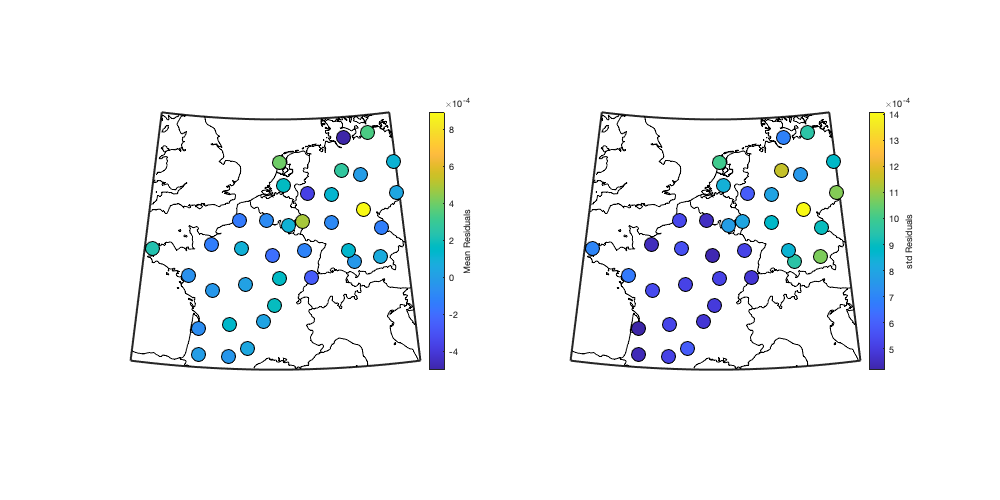

err_nan_m = splitapply(@mean, Tfit30.error, Tfit30.radar);
err_nan_s = splitapply(@std, Tfit30.error, Tfit30.radar);
figure('position',[0 0 1000 500]);
subplot(1,2,1); hold on; h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','k')
scatterm([dc.lat], [dc.lon], 200,err_nan_m,'filled','MarkerEdgeColor','k'); c=colorbar;c.Label.String='Mean Residuals';
subplot(1,2,2); hold on; h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
bordersm('countries','k')
scatterm([dc.lat], [dc.lon], 200,err_nan_s,'filled','MarkerEdgeColor','k'); c=colorbar;c.Label.String='std Residuals';

### Residual with density

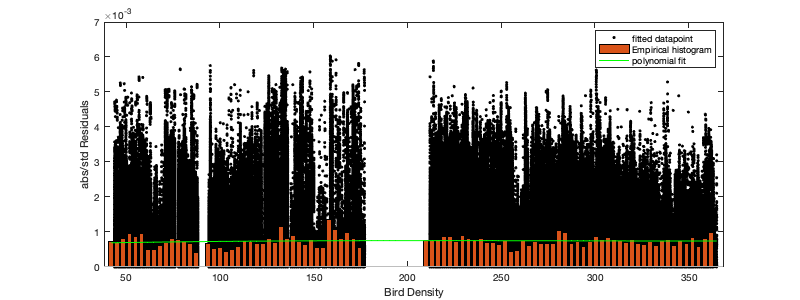

[Y,E] = discretize(Tfit30.time,100);
[G,ID] = findgroups(Y);
varBinResiduals=nan(size(E));
varBinResiduals(ID) = splitapply(@std,Tfit30.error,G);
% p = polyfit(Tfit.dens_tt,abs(mdl.Residuals.Raw),3);
p = polyfit(E(~isnan(varBinResiduals)),varBinResiduals(~isnan(varBinResiduals)),3);
figure('position',[0 0 800 300]); box on; hold on;
plot(Tfit30.time, abs(Tfit30.error),'.k');
bar(E,varBinResiduals);
plot(E,polyval(p,E),'-g')
yline(0,'w'); ylabel('abs/std Residuals'); xlabel('Bird Density');
legend('fitted datapoint','Empirical histogram','polynomial fit')

[Y,E] = discretize(Tfit30.dens_tt,100);
[G,ID] = findgroups(Y);
varBinResiduals=nan(size(E));
varBinResiduals(ID) = splitapply(@std,Tfit30.error,G);
% p = polyfit(Tfit.dens_tt,abs(mdl.Residuals.Raw),3);
p_abserror = polyfit([E(~isnan(varBinResiduals)) 10^9],[varBinResiduals(~isnan(varBinResiduals)) 0],3);

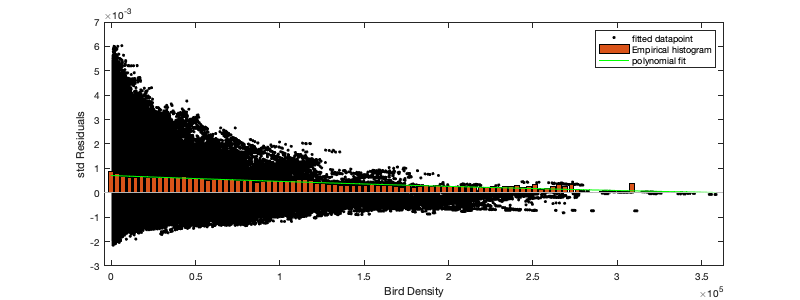

figure('position',[0 0 800 300]); box on; hold on;
plot(Tfit30.dens_tt, (Tfit30.error),'.k');
bar(E,varBinResiduals);
plot(E,polyval(p_abserror,E),'-g')
yline(0,'w'); ylabel('std Residuals'); xlabel('Bird Density');
legend('fitted datapoint','Empirical histogram','polynomial fit')

### Model residual absolute value

% Tfit30.abserror=abs(Tfit30.error);
% stepwiseglm(Tfit30,'constant', 'ResponseVar', 'abserror',  'PredictorVars', {'lat','lon'},'Verbose',0,'Upper','poly22') % same with ,'Criterion','bic'
% stepwiseglm(Tfit30,'constant', 'ResponseVar', 'abserror',  'PredictorVars', 'dens_tt','Verbose',0,'Upper','poly5')
% modelspec = 'abserror ~ lat + lon + lat:lon + lat^2 + lon^2 + dens_tt';
% mdlabserror = fitglm(removevars(Tfit30,{'ratio','NNT','time','radar','error'}), modelspec)
% mdlabserror = fitglm(Tfit30.dens_tt,Tfit30.abserror,'poly2');

## Save

% compactmdlabserror = compact(mdlabserror);
compactmdl = compact(mdl);
save('./data/ratio','windturbine_minheight','windturbine_maxheight','p_abserror','compactmdl')